%Here we are going to load the created map data.
g = 4;
load("2D\occupancy_map_data"+g+".mat")
map = Map;


load ("2D\occupancy_map"+g+".mat")
Map = occupancyMap(omap);


%Here we are going to set up the start and end parameters, 
%start_orientation and goal_orinetation parameter will determine how the
%algorithm will connect to it, it has to be given in radian
%

start_x = 5;
start_y = 8;
start_orientation = 0;
goal_x = 17;
goal_y = 17;
goal_orientation = 0;

robot_pose = [start_x start_y start_orientation];
goal_pose = [goal_x goal_y goal_orientation];

%For it to work we have to create a statSpace object
%The stateSpaceSE2 object stores parameters and states in the SE(2) state space, 
%which is composed of state vectors represented by [x, y, θ]. 
%x and y are Cartesian coordinates, and θ is the orientation angle. 
% The object uses Euclidean distance to calculate distance and uses linear 
% interpolation to calculate translation and rotation of the state.
ss = stateSpaceSE2;
%We have to give it the bounds because it can not reach the first and last
%one meter in each direction
ss.StateBounds = [[1 19]; [1 19]; [-pi pi]];
%The validatorOccupancyMap object validates states and discretized 
%motions based on the value in a 2-D occupancy map.
%An occupied map location is interpreted as an invalid state.
sv = validatorOccupancyMap(ss);

%We have to give the sv variable our map, and here we also give it the
%bounds
sv.Map = Map;
sv.ValidationDistance = 0.01;
ss.StateBounds = [ss.StateBounds];


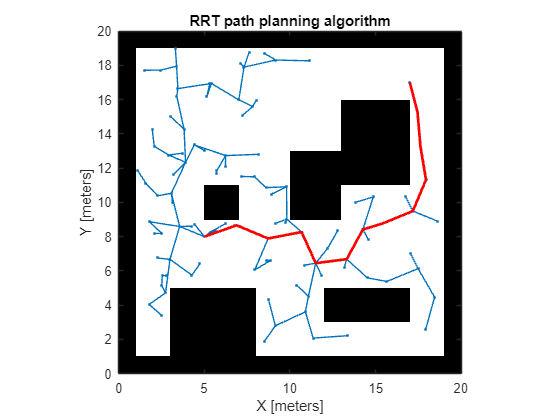

%The plannerRRT is responsible for creating the planner and the
%plan will create a path from the start point to end point
planner = plannerRRT(ss,sv,MaxConnectionDistance=2);
[pathObj, solvInf] = plan(planner, robot_pose, goal_pose);  

%We are going to show the path
show(Map)
hold on

% Here we are going to see, how the trees looks like, how it tried to
% expand
plot(solvInf.TreeData(:,1),solvInf.TreeData(:,2),'.-')
% Draw path
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2)
title("RRT path planning algorithm")